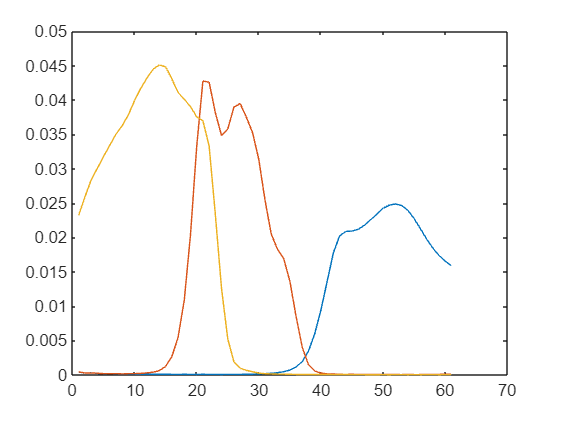

% 1.1

load("Ad.mat");
load("Ad2.mat");

plot(Ad);

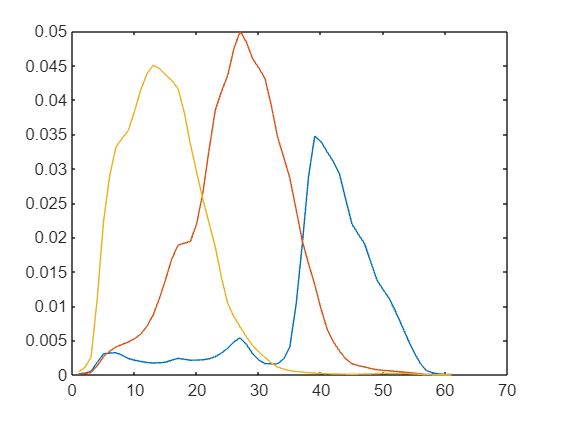

figure
plot(Ad2);


% Ad has more overlap --> shifts in color
% Double peaks, maybe lack some information in color depth
% Ad2 has more separation and better peaks, resulting in a more "accurate"
% picture

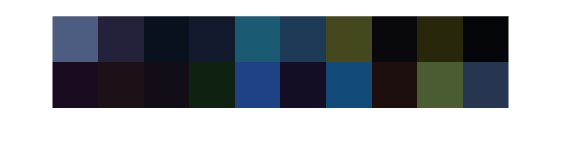

% 1.2

load("chips20.mat");
load("illum.mat");

% .* = Element-wise multiplication
% ' = Transpose
% d = Ad^t * e^t //t = transpose
d = Ad'*(chips20(:,:).*CIED65)';
d2 = Ad2'*(chips20(:,:).*CIED65)';

showRGB(d');

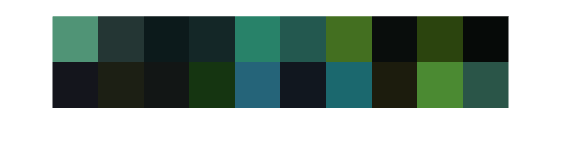

showRGB(d2');


% Ad has better dark green (Wave form more to left)
% Ad2 has brighter colors, more saturation and vibrant, Ad is more dark

% 2.1

e = ones(1,61);

Norm_Ad = Ad'*e';
Norm_Ad2 = Ad2'*e';

% The lower peaks will divide with a smaller number, resulting in a larger
% peak, meanwhile the high peaks will not grow as much

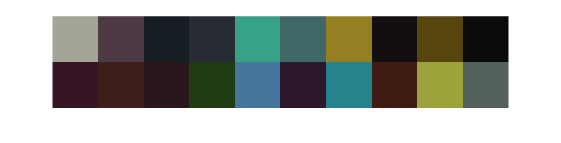

% 2.2 

RGB_D65_Calibrated_Ad = (Ad'*(chips20(:,:).*CIED65)')./Norm_Ad;
RGB_D65_Calibrated_Ad2 = (Ad2'*(chips20(:,:).*CIED65)')./Norm_Ad2;

showRGB(RGB_D65_Calibrated_Ad');

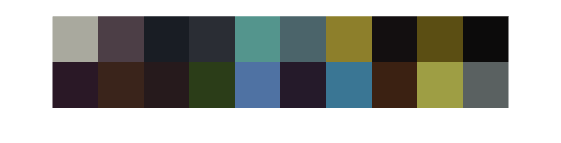

showRGB(RGB_D65_Calibrated_Ad2');

% Its alot different. The colors are more accurate and same.
% We can still see some flaws in the green colors, and some in the red, but
% its alot better

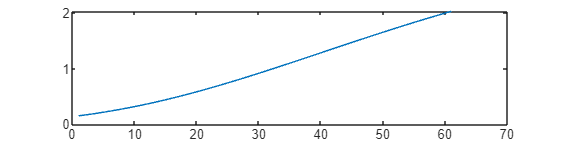

% 2.3

plot(CIEA) % Outdoor

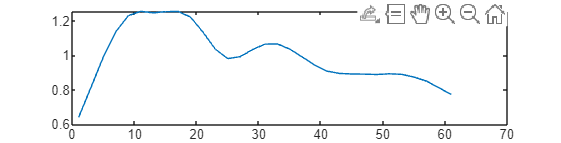

plot(CIED65) % Indoor

% We see that the intensity is larger outdoor
% More warm light from outdoor but "Constant"
% Indoor can see wave peaks more clear

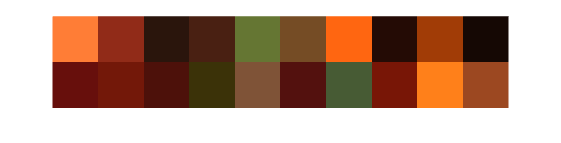

% 2.4 

RGB_CIEA_Calibrated_Ad = (Ad'*(chips20(:,:).*CIEA)')./Norm_Ad;

showRGB(RGB_CIEA_Calibrated_Ad') % Outdoor same light

showRGB(RGB_D65_Calibrated_Ad') % Indoor same light

% If we not adjust for the strong red in outdoor, the colors will be more
% red, same for indoor where blue is more strong

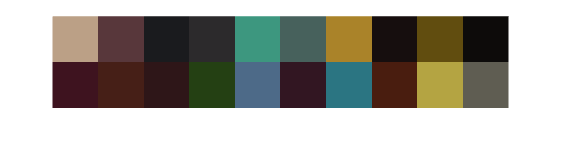

% 2.5
load("Ad.mat");
load('chips20.mat')
load('illum.mat')
R = ones(1,61);

Calibrated_CIEA = Ad'*(R.*CIEA)';
RGB_RAW_CIEA = Ad'*(chips20(:,:).*CIEA)'./Calibrated_CIEA;

Calibrated_D65 = Ad'*(R.*CIED65)';
RGB_RAW_D65 = Ad'*(chips20(:,:).*CIED65)'./Calibrated_D65;

showRGB(RGB_RAW_CIEA') % Outdoor

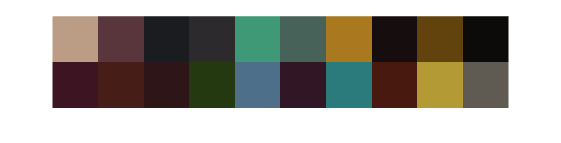

showRGB(RGB_RAW_D65')  % Indoor